# Implement Simultaneous Localization And Mapping (SLAM) with Lidar Scans

load('offlineSlamData.mat');
maxLidarRange = 8;
mapResolution = 20;
slamAlg = lidarSLAM(mapResolution, maxLidarRange);

## Modify Closure and Scan Sensitivity

Using higher loop closure threshold helps reject false positives in loop closure identification process. However, keep in mind that a high-score match may still be a bad match. 

Using a higher loop closure search radius allows the algorithm to search a wider range of the map around current pose estimate for loop closures.

slamAlg.LoopClosureThreshold =  190;  %og: 210
slamAlg.LoopClosureSearchRadius = 8; %og: 8

for i=1:10
    [isScanAccepted, loopClosureInfo, optimizationInfo] = addScan(slamAlg, scans{i});
    if isScanAccepted
        fprintf('Added scan %d \n', i);
    end
end

Added scan 1 
Added scan 2 
Added scan 3 
Added scan 4 
Added scan 5 
Added scan 6 
Added scan 7 
Added scan 8 
Added scan 9 
Added scan 10 


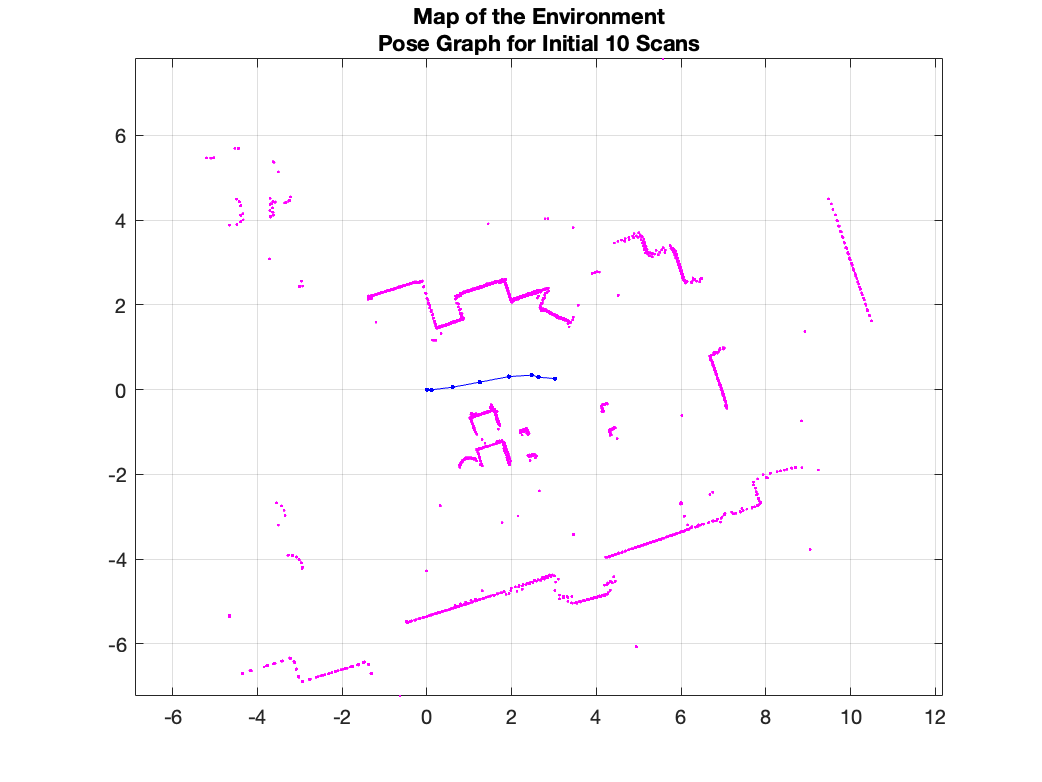


figure;
show(slamAlg);
title({'Map of the Environment','Pose Graph for Initial 10 Scans'});

## Observe the Effect of Loop Closures and the Optimization Process

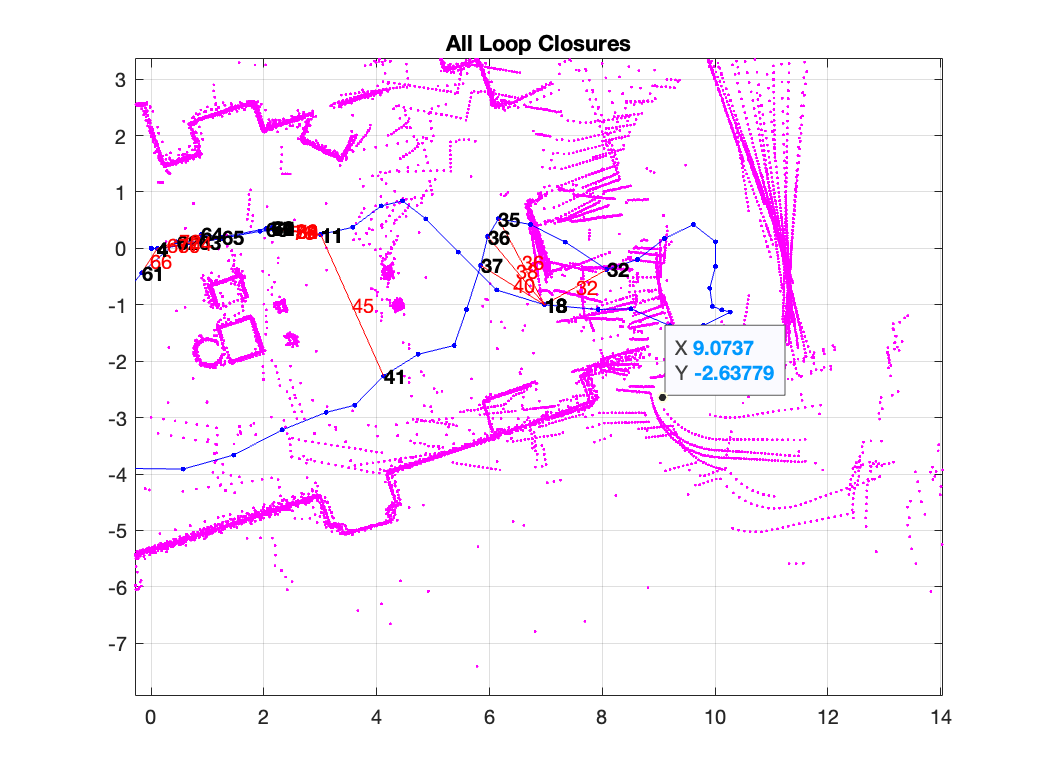

firstTimeLCDetected = false;

figure;
for i=10:length(scans)
    [isScanAccepted, loopClosureInfo, optimizationInfo] = addScan(slamAlg, scans{i});
    if ~isScanAccepted
        continue;
    end
    show(slamAlg, 'Poses', 'off');
    hold on;
    show(slamAlg.PoseGraph); 
    hold off;
    firstTimeLCDetected = true;
    drawnow
end
title('All Loop Closures'); % red links are closures

% Use the "exportgraphics" function to save the figure as a PNG with white background
exportgraphics(gcf, 'closures.png', 'BackgroundColor', 'white');

## Visualize the Constructed Map and Trajectory of the Robot

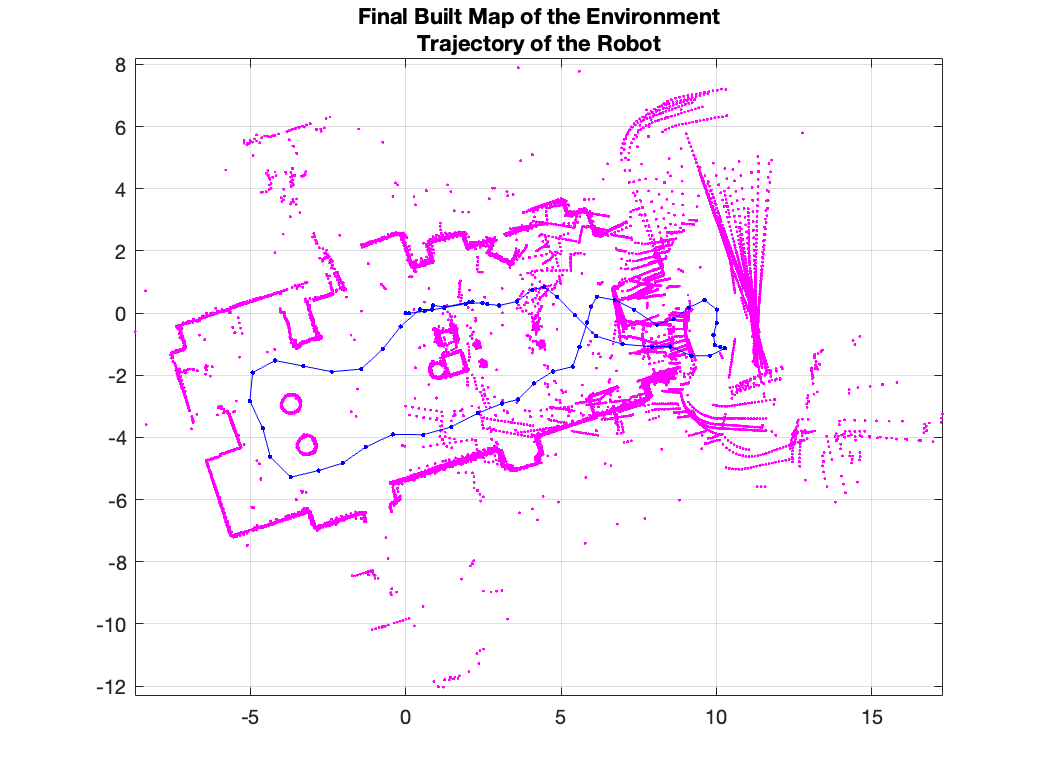

figure
show(slamAlg);
title({'Final Built Map of the Environment', 'Trajectory of the Robot'});

% Use the "exportgraphics" function to save the figure as a PNG with white background
exportgraphics(gcf, 'map.png', 'BackgroundColor', 'white');

## Build Occupancy Grid Map

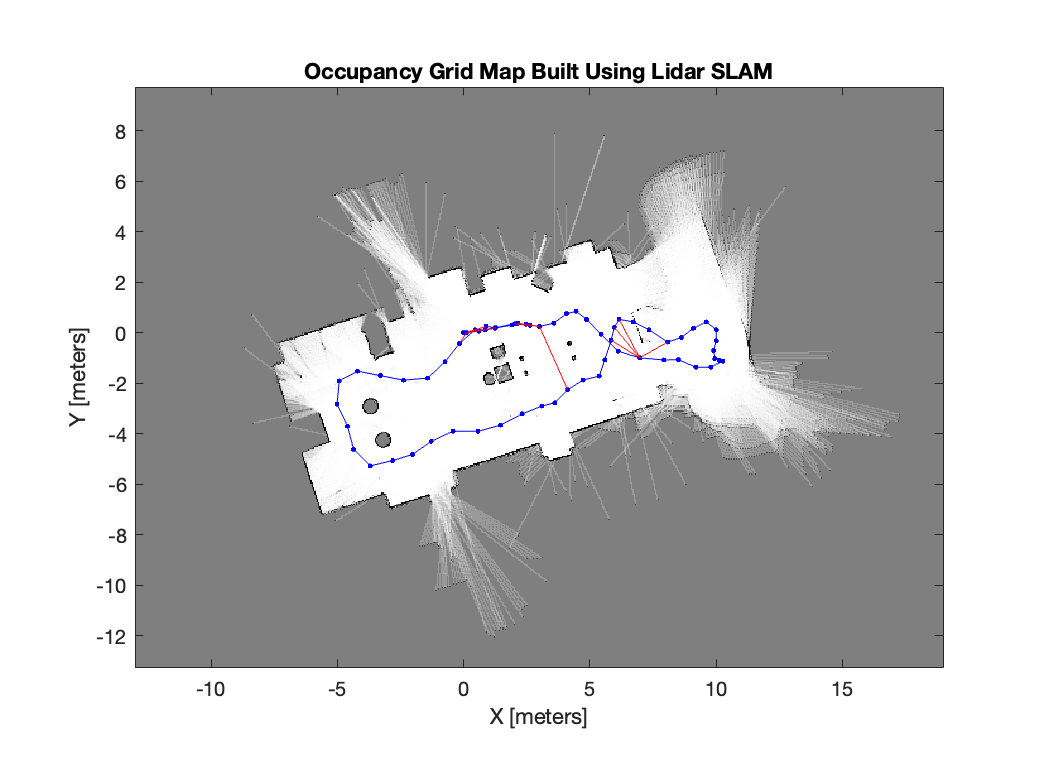

[scans, optimizedPoses]  = scansAndPoses(slamAlg);
map = buildMap(scans, optimizedPoses, mapResolution, maxLidarRange);
figure; 
show(map);
hold on
show(slamAlg.PoseGraph, 'IDs', 'off');
hold off
title('Occupancy Grid Map Built Using Lidar SLAM');

% Use the "exportgraphics" function to save the figure as a PNG with white background
exportgraphics(gcf, 'occupancyGrid.png', 'BackgroundColor', 'white');